**Process Data and change variable names to be easier to work with**

clear
load storageTest4.mat
LIDAR.x = storage(1:end,1);
LIDAR.y = storage(1:end,2);
number_of_scans = size(storage,1)/360;
LIDAR.controlFlag = ones(size(storage,1),1);
last_x = storage(1,3);
for n = [2:size(LIDAR.controlFlag)]
    if storage(n,3) == last_x
        LIDAR.controlFlag(n) = LIDAR.controlFlag(n-1);
    else
        last_x = storage(n,3);
        LIDAR.controlFlag(n) = LIDAR.controlFlag(n-1)+1;
    end
end

LIDAR.x1 = LIDAR.x(not(and(LIDAR.x<1,and(LIDAR.x>0.25,and(LIDAR.y<-2,LIDAR.y>-3)))));
LIDAR.y1 = LIDAR.y(not(and(LIDAR.x<1,and(LIDAR.x>0.25,and(LIDAR.y<-2,LIDAR.y>-3)))));
LIDAR.controlFlag = LIDAR.controlFlag(not(and(LIDAR.x<1,and(LIDAR.x>0.25,and(LIDAR.y<-2,LIDAR.y>-3)))));
LIDAR.x = LIDAR.x1;
LIDAR.y = LIDAR.y1;

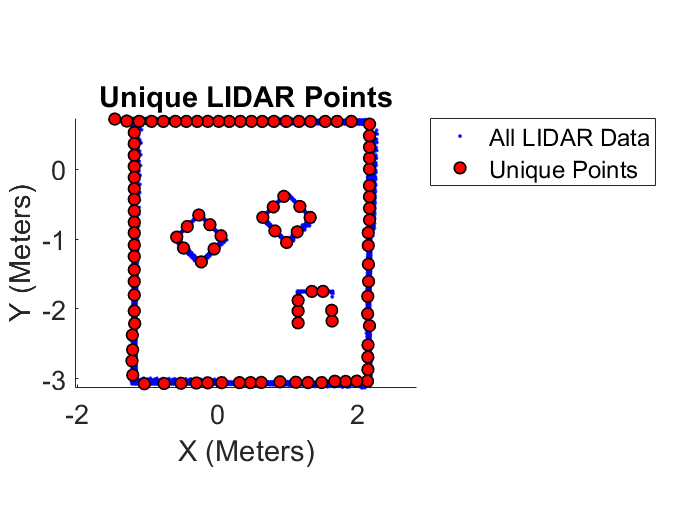

rp = 0.15;
clf; hold on;
GAP = [LIDAR.x(1),LIDAR.y(1)];
for n = [2:size(LIDAR.x,1)]

    newp = [LIDAR.x(n),LIDAR.y(n)];
    
    difference = abs(GAP-newp); %find the difference between the new point and every old point
    logical_diff = difference<rp; %is the difference in x or y smaller than the radius
    logical_diff2 = double(logical_diff(:,1))+double(logical_diff(:,2))==2; %is the radius smaller in both x and y
    sum_logical_diff2 = sum(logical_diff2); %add the matrix to do a math
    
    if sum_logical_diff2 == 0
        GAP = [GAP;LIDAR.x(n),LIDAR.y(n)];
    %else
    %    plot(newp(1),newp(2),"b.")
    end
end
plot(LIDAR.x,LIDAR.y,"b.","DisplayName","All LIDAR Data")
plot(GAP(:,1),GAP(:,2),"ko","MarkerSize",7,"MarkerFaceColor","r","LineWidth",1,"DisplayName","Unique Points")
axis equal; xlabel("X (Meters)"); ylabel("Y (Meters)"); legend("Location","bestoutside"); title("Unique LIDAR Points");
set(gca, 'color', [1 1 1])
set(gcf, 'color', [1 1 1])
set(gca, "FontSize",16);

%save equations_symbolic.mat sym_barrels sym_gradient sym_sources grad_sym xs ys

expansion = 0.01;
barrel_multiplyer = 7; %multiplyer of barrel
source_multiplyer = 1; %multiplyer of sources

point_spacing = 0.1;
[X,Y] = meshgrid(min(LIDAR.x)-expansion:point_spacing:max(LIDAR.x)+expansion,min(LIDAR.y)-expansion:point_spacing:max(LIDAR.y)+expansion);
source = @(x,y,a,b) 5.*log(sqrt((x-a).^2+(y-b).^2));
sink = @(x,y,a,b,scale) scale.*-1.*log(sqrt((x-a).^2+(y-b).^2));
sources = 0;
syms xs ys
sym_sources = 0; %low points
for n = [1:size(GAP,1)]
    sources = sources+source(X,Y,GAP(n,1),GAP(n,2)); %do it mathematically
    sym_sources = sym_sources+log(sqrt((xs-GAP(n,1)).^2+(ys-GAP(n,2)).^2)); %do it symbolically
end

points_1d = 5;
barrel_count = 1;
barrels = 0;
sym_barrels = 0;
barrel_points = [0,0];
size_offset = 0.2;
ny = [linspace(-2.5+size_offset,-2.5-size_offset,points_1d)]';
nx = [linspace(0.75-size_offset,0.75+size_offset,points_1d)]';
for n1 = [1:points_1d]
    for n2 = [1:points_1d]
        sym_barrels = sym_barrels + barrel_multiplyer*-1*log(sqrt((xs-nx(n1,1)).^2+(ys-ny(n2,1)).^2));
        barrels = barrels + sink(X,Y,nx(n1,1),ny(n2,1),barrel_multiplyer);
        barrel_count = barrel_count+1;
        barrel_points = [barrel_points;nx(n1,1),ny(n2,1)];
    end
end
barrel_points = barrel_points(2:end,:);

sym_gradient = (sym_sources+sym_barrels)/(n+barrel_count); %high points
%sym_gradient = (sym_sources)/(n);


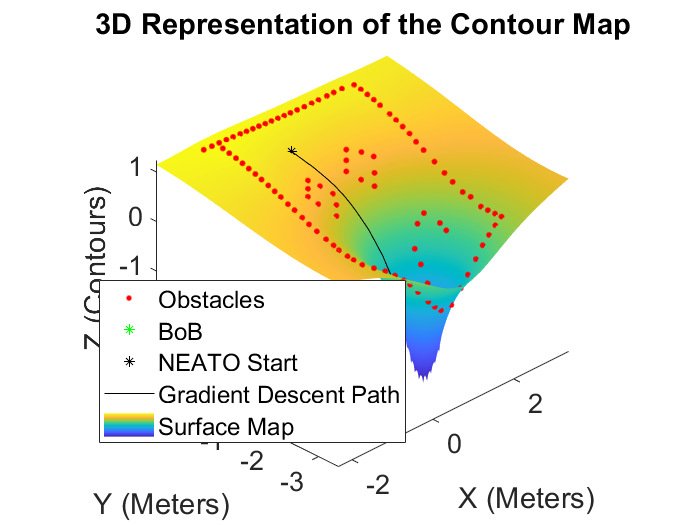

load DriveCodeV4_Storage_2.mat
z_global = 0;
for n = [1:size(x_global,1)]
    z_global(n,1) = vpa(subs(-sym_gradient,[xs ys],[round(x_global(n,1),2) round(y_global(n,1),2)]));
end
GAP_height = 0;
for n = [1:size(GAP,1)]
    GAP_height(n) = vpa(subs(-sym_gradient,[xs ys],[round(GAP(n,1),2) round(GAP(n,2),2)]));
end
clf; hold on;
z_height = 0;
gradient_ascent = (sources+barrels)/(n+barrel_count); %high point added here
%plot3(GAP(:,1),GAP(:,2),zeros(size(GAP,1))+z_height,"r.","MarkerSize",10)
plot3(GAP(:,1),GAP(:,2),GAP_height,"r.","MarkerSize",10,"DisplayName","Obstacles")
plot3(0.75,-2.5,vpa(subs(-sym_gradient,[xs ys],[0.75 -2.5])),"g*","DisplayName","BoB")
plot3(0,0,vpa(subs(-sym_gradient,[xs ys],[0 0])),"k*","DisplayName","NEATO Start")
%plot3(barrel_points(:,1),barrel_points(:,2),zeros(size(barrel_points,1))+z_height,"gs")
%surf(X,Y,-gradient_ascent,'EdgeColor',"flat")
plot3(x_global,y_global,z_global,"k-","DisplayName","Gradient Descent Path")
fsurf(-sym_gradient,"DisplayName","Surface Map","EdgeColor","none")
axis equal; xlabel("X (Meters)"); ylabel("Y (Meters)"); zlabel("Z (Contours)"); title("3D Representation of the Contour Map"); legend("Location","best")
view([-45,30]); set(gca, "FontSize",16);

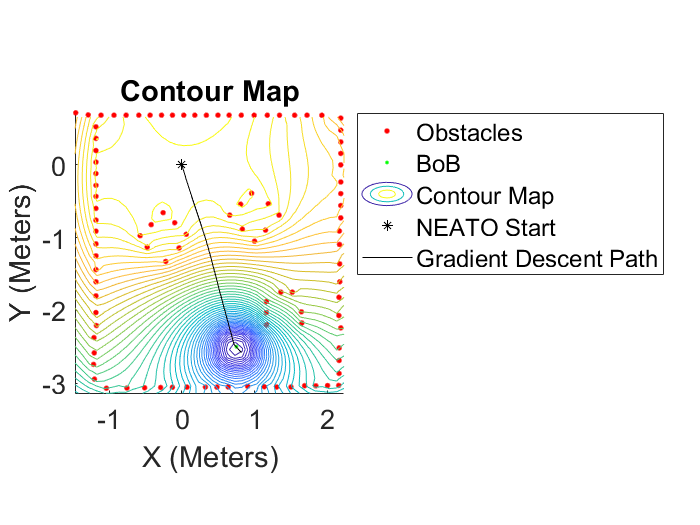


clf; hold on; axis equal
plot(GAP(:,1),GAP(:,2),"r.","MarkerSize",10,"DisplayName","Obstacles")
plot(0.75,-2.5,"g.","DisplayName","BoB")
%plot(barrel_points(:,1),barrel_points(:,2),"gs")
contour(X,Y,-gradient_ascent,50,"DisplayName","Contour Map")
xlabel("X (Meters)"); ylabel("Y (Meters)")
plot(0,0,"k*","DisplayName","NEATO Start")
set(gca, 'color', [1 1 1])
set(gcf, 'color', [1 1 1])
plot(x_global,y_global,"k-","DisplayName","Gradient Descent Path")
legend("location","bestoutside"); set(gca, "FontSize",16); title("Contour Map")

grad_sym = gradient(-sym_gradient);
gx = @(x1, y1) vpa(subs(grad_sym(1),[xs ys], [x1 y1]));
gy = @(x1, y1) vpa(subs(grad_sym(2),[xs ys], [x1 y1]));
for n1 = [1:size(X,1)]
    for n2 = [1:size(X,2)]
        U(n1,n2) = gx(X(n1),Y(n2));
        V(n1,n2) = gy(X(n1),Y(n2));
    end
end

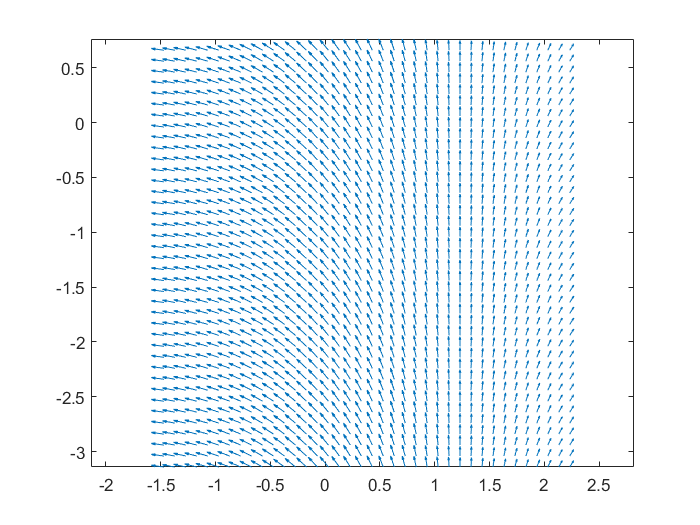

clf; hold off;
quiver(X,Y,U,V); hold on; axis equal;

%contour(X,Y,-gradient_ascent,50,"DisplayName","Contour Map")
%contourf(sym_gradient);

r_0 = [0;0]

r_0 =      0
     0


%delta = 0.9;
delta = 1;
lambda_0 = 1.14;
lambda_0 = 0.1;
tolerance = 1e-2;
n_max = 100;

syms x y
sym_gradient = subs(sym_gradient,[xs ys],[x y]);
[R,R_s] = gradient_ascent_calculator(sym_gradient,r_0,delta,lambda_0,tolerance,n_max);

clf;
plot(GAP(:,1),GAP(:,2),"r.","MarkerSize",10)
%xlim([-1.7,1.5]);
axis equal
hold on;
fcontour(-sym_gradient,[-2,2.5,-3.25,1]);
plot(R(:, 1), R(:, 2), "b.-","DisplayName","Path")
plot(R(1,1),R(1,2),"bo","DisplayName","r_0")




clf; hold on; axis equal
plot(GAP(:,1),GAP(:,2),"r.","MarkerSize",10)
plot(0.75,-2.5,"g*")
contour(X,Y,-gradient_ascent,50)
plot(R(:, 1), R(:, 2), "r-","DisplayName","Path")
plot(R(1,1),R(1,2),"ro","DisplayName","r_0")

%save sym_gradient.mat sym_gradient

% wheel_base = 0.235;
% lambda = 0.1;
% 
% syms x y
% f = sym_gradient;
% grad = gradient(f, [x y]);
% 
% heading = [0,1];
% position = [0,0];
% 
% angular_speed= 0.1;
% linear_speed = 0.01;
% 
% 
% %pub = rospublisher('/raw_vel');
% msg = rosmessage(pub);
% 
% msg.Data = [0,0];
% send(pub, msg);
% pause(2);
% 
% 
% placeNeato(position(1), position(2), heading(1), heading(2));
% pause(2);
% should_stop = false;
% 
% while ~should_stop
%     grad_value = double(subs(grad, {x,y}, {position(1), position(2)}));
%     cross_product = cross([heading; 0], [grad_value;0]);
%     turn_direction = sign(cross_product(3));
%     turn_angle = asin(norm(cross_product)/(norm(headind)*norm(grad_value)));
%     
%     turn_time = double(turn_angle) / angular_speed;
%     
%     msg.Data = [-turn_direction*angular_speed*wheel_base/2,
%         turn_direction*angular_speed*wheel_base/2];
%     send(pub,msg);
%     
%     start_turn = rostic;
%     while rostoc(start_turn) < turn_time
%         pause(0.01);
%     end
%     
%     heading = grad_value;
%     
%     forward_distance = norm(grad_value*lambda);
%     forward_time = forward_distance/linear_speed;
%     msg.Data = [linear_speed, linear_speed];
%     send(pub,msg);
%     start_forward = rostic;
%     while rostoc(start_forward) < forward_time
%         pause(0.01)
%     end
%     
%     position = position + grad_value*lambda;
%     should_stop = forward_distance < 0.01;
% end
% 
% msg.Data = [0,0];
% send(pub,msg);


function [R,R_s] = gradient_ascent_calculator(f,r_0,delta,lambda_0,tolerance,n_max)
% inputs:
%   f = (symbolic) equation to perform gradient ascent on, must be a 1x1
%   symbolic equation using variables x and y
%   r_0 = (float) initial guess, must be 1x2 (formatted as [x;y])
%   delta = (float) stepsize decay parameter; should have delta < 1
%   lambda_0 = (float) initial stepsize
%   tolerance = (float) gradient convergence tolerance
%   n_max = (int) maximum iteration count
% outputs:
%   R = (matrix) full iteration history


    %inform user that this could take a while if the n_max is big
    if n_max >= 200
       warning("n_max is larger than 200, this could take a while.") 
    end
    %if n_max is 0, throw an error
    if n_max <= 0
        error("n_max must be larger than 0")
    end
    %if r_0 is a 2x1, fix
    if size(r_0) == [1,2]
        warning("r_0 is 1x2 instead of 2x1. It will automatically be converted to a 2x1.")
        r_0 = r_0';
    end

    
    %redefine symbolic vars
    syms x y
    %f_fun = @(xn,yn) vpa(subs(f,[x y],[xn yn]));
    gradient_f = gradient(f);
    %create a function for the gradient
    f_grad = @(xn,yn) vpa(subs(gradient_f,[x y],[xn yn]));
    f_s_grad = @(xn,yn) subs(gradient_f,[x y],[xn yn]);
    
    %initialize variables
    n = 0;
    lambda = lambda_0;
    R = [r_0']; %this output is flipped from the input (r_0 is stored as a 1x2 instead of a 2x1)
    R_s = [r_0'];
    r_i = r_0;
    r_s_i = r_0;
    grad_i = f_grad(r_0(1),r_0(2));
    grad_s_i = f_s_grad(r_0(1),r_0(2));
    
    while (n < n_max) && (norm(grad_i) > tolerance)
        %lambda = 0.1;
        %gradient ascent step
        r_i = r_i + lambda * grad_i;
        r_s_i = r_s_i + lambda * grad_s_i;
        
        %iterate vars
        grad_i = f_grad(r_i(1),r_i(2));
        %lambda = delta*lambda;
        n = n+1;
        R(end+1,:) = r_i'; %cannot be preallocated due to an unknown final size
        R_s(end+1,:) = r_s_i';
    end
    if n >= n_max
        warning("maximum number of steps has been exceded, terminating program now.")
    end
end
